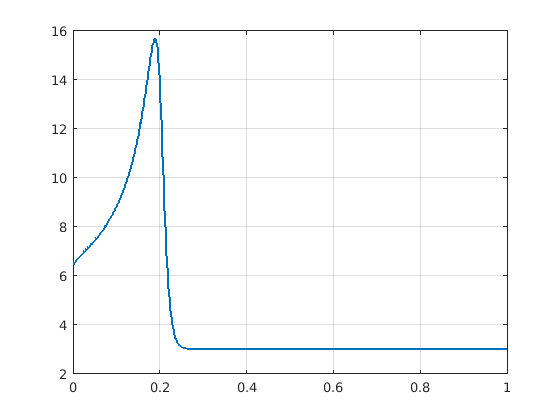

clc; clear all; close all;

% Basic data:
J_m = 0.005; % kg*m^2
J_eff = J_m;

V_p = 220; % V
p = 2;
f_s = 50; % Hz
R_s = 2; % Ohm
R_r = 2.5; % Ohm
L_s = 0.025; % H
L_r = 0.015; % H

M_fr = 3; % Nm
omega_fr = 20; % rad/s

simTime = 1; % s
t = 0; % s
dt = 10^-5; % s
idx = 1; % counter

omega_m = 0;


while(t <= simTime)
    % Calculations
    omega_s = 2/p * 2*pi*f_s;
    s = (omega_s-omega_m)/omega_s;

    M_L = M_fr*tanh(omega_m/omega_fr);
    M_m = (3*R_r*V_p^2)/( (s*omega_s) * ( (R_s+R_r/s)^2 + omega_s^2 * (L_s+L_r)^2 ) );


    omega_mDot = (M_m - M_L)/J_eff;
    % Logging
    timePlot(idx) = t;
    M_m_plot(idx) = M_m;

    % Time Integration
    omega_m = omega_m + omega_mDot * dt;

    % Update Variables
    t = t + dt;
    idx = idx + 1;

end

% Plotting
plot(timePlot, M_m_plot, 'LineWidth', 2)
grid